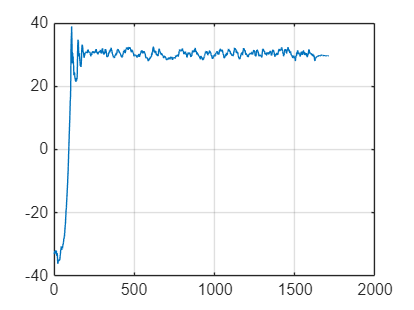

% data import
m1_train = importdata('m1_data.csv');
m2_train = importdata('m2_data.csv');
x_train_m1 = m1_train(:,1);
y_train_m1 = m1_train(:,2);
x_train_m2 = m2_train(:,1);
y_train_m2 = m2_train(:,2);

%data plot
plot(y_train_m1);
grid on

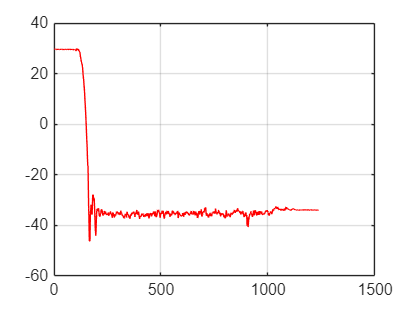

plot(y_train_m2, 'r');
grid on


te = 0.01; %Perioada de esantionare
fs = 1/te; %Frecventa
fc = 5/6 %Frecventa de taiere

fc = 0.8333

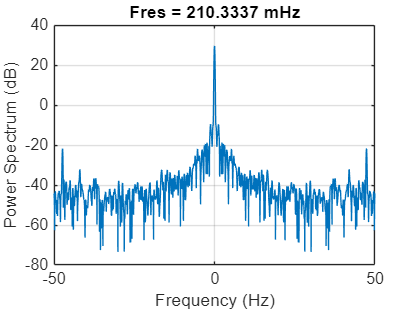


%spectrul de frecvente
pspectrum(y_train_m1,fs,'Leakage',0,'TwoSided',true)

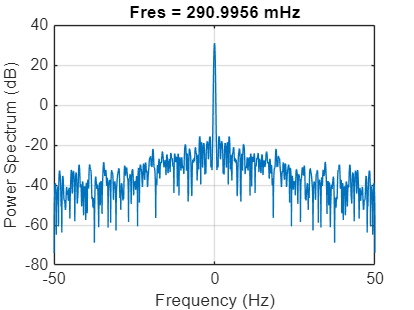

pspectrum(y_train_m2,fs,'Leakage',0,'TwoSided',true)

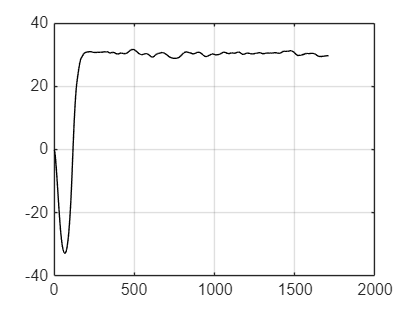


%butterworth filter
[b, a] = butter(2, fc/(fs/2),'low'); % coeficentii filtrului
m1_filtrat = filter(b, a, y_train_m1); %filtrarea motor 1
m2_filtrat = filter(b, a, y_train_m2); %filtrarea motor 2

%filtered data
plot(m1_filtrat, 'k');
grid on

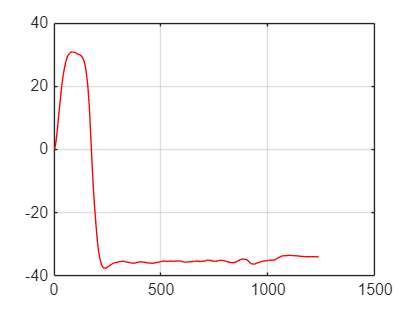

plot(m2_filtrat, 'r');
grid on


% plot(out_b_lp_copy,'r') %Pentru lowpass plot(filtru,'r')

s = tf('s');

%regulator M1
Kp1 = PID_M1.Kp;

Unable to resolve the name 'PID_M1.Kp'.

Ti1 = PID_M1.Ti;
G1 = tf(TF_M1.Numerator, TF_M1.Denominator)
Reg1 = Kp1*(1+  (1/(s*Ti1)))
Gd1 = series(Reg1,G1)
G01 = feedback(Gd1,1)
step(G01)
stepinfo(G01)

%regulator M2
Kp2 = PID_M2.Kp;
Ti2 = PID_M2.Ti;
G2 = tf(TF_M2.Numerator, TF_M2.Denominator)
Reg2 = Kp2*(1+  (1/(s*Ti2)))
Gd2 = series(Reg2,G2)
G02 = feedback(Gd2,1)
step(G02)
stepinfo(G02)

%discretizare
Regz1 = c2d(Reg1,te,'foh')
Regz2 = c2d(Reg2,te,'foh')
Regz1.Variable = 'z^-1'
Regz2.Variable = 'z^-1'
[uzd1, yzd1] = tfdata(Regz1, 'v')
[uzd2, yzd2] = tfdata(Regz2, 'v')